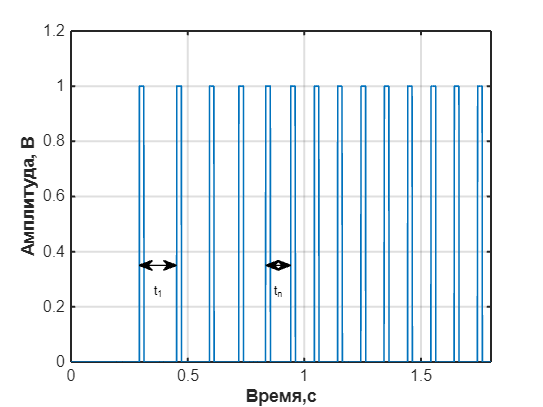

%% Параметры
fs      = 2e4;            % частота дискретизации, Гц
tEnd    = 1.8;            % длительность окна, с
t       = 0:1/fs:tEnd;

f0      = 4;              % частота импульсов в t=0, Гц
f1      = 10;             % частота после 1 c (равномерная), Гц
tRamp   = 1.0;            % длительность разгона (0..1 c)
t0      = 0.1;           % первый импульс начинается после t0
tau     = 0.02;          % длительность импульса, с
A       = 1;              % амплитуда

%% Задание частоты: линейная от f0 до f1 на [0,1], дальше f1
f = f0 + (f1 - f0) .* min(t, tRamp) ./ tRamp;

% Накопленная фаза в циклах (интеграл частоты)
s  = cumtrapz(t, f);                    % в циклах
s0 = interp1(t, s, t0);                 % чтобы стартовать с импульса в t0

% Моменты импульсов = моменты пересечения целых значений фазы
k      = floor(s - s0);
edges  = find(diff(k) > 0);             % индексы фронтов
tk     = t(edges);
tk     = tk(tk >= t0);                  % берём импульсы после t0

%% Формирование прямоугольных импульсов
x = zeros(size(t));
for i = 1:numel(tk)
    x(t >= tk(i) & t < tk(i) + tau) = A;
end

%% График
figure('Color','w');
plot(t, x, 'LineWidth', 1.2); grid on
xlim([0 tEnd]); ylim([0 1.2])
xlabel('Время,с','FontSize',14, 'FontWeight','bold'); ylabel('Амплитуда, В','FontSize',14, 'FontWeight','bold');
set(gca, 'FontSize',12, 'Linewidth', 1.5)
%% Стрелки t1 и t_n
ax = gca; yA = 0.35;                          % высота стрелок по Y
addPeriodArrow(ax, tk(1), tk(2), yA, 't_1');  % первый период
addPeriodArrow(ax, tk(5), tk(6), yA, 't_n'); % последний период

%% Вспомогательная функция для стрелок
function addPeriodArrow(ax, x1, x2, y, lbl)
    fig = ancestor(ax,'figure');
    xn = @(x) ax.Position(1) + (x-ax.XLim(1))/diff(ax.XLim)*ax.Position(3);
    yn = @(yy) ax.Position(2) + (yy-ax.YLim(1))/diff(ax.YLim)*ax.Position(4);
    annotation(fig,'doublearrow', [xn(x1) xn(x2)], [yn(y) yn(y)]);
    text(mean([x1 x2]), y - 0.08*(ax.YLim(2)-ax.YLim(1)), lbl, ...
        'HorizontalAlignment','center','Interpreter','tex');
end
exportgraphics(gcf,'img/encoder.pdf','ContentType','vector','BackgroundColor','none');